[images labels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',20000 ,0);
[trainimages trainlabels testimages testlabels]  = splitdata(images,labels, 0.8);

# Wavelet Study

[trainimages trainlabels testimages testlabels]  = splitdata(images,labels, 0.8);
[trainfeatures] = extractfeatureswithWaveletScattering(trainimages);

**Dimensionality Reduction**

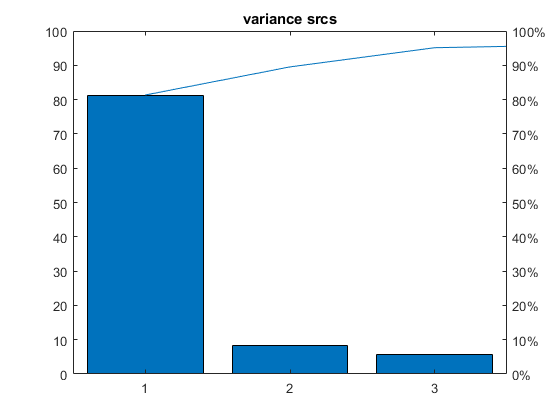

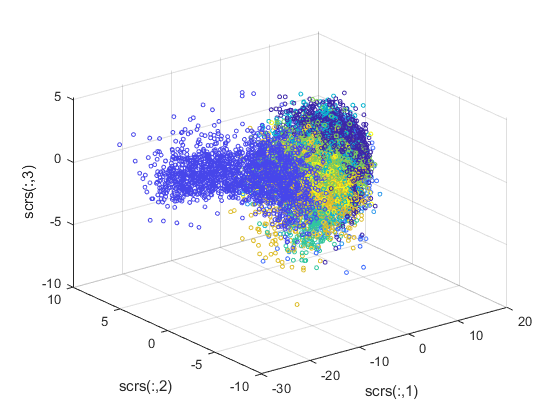

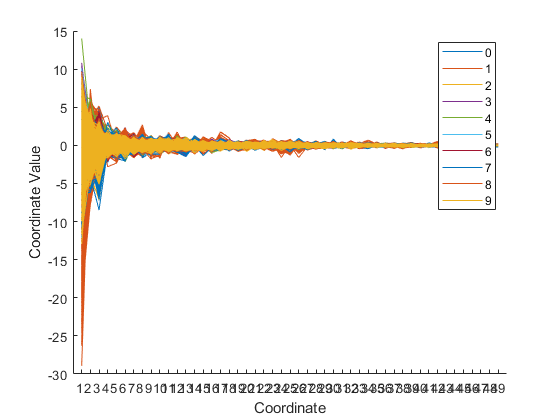

load wavelet.mat
[trainfeaturesNorm, trainpcs, trainscrs] = study_of_data(trainfeatures, trainlabels);

a = [trainscrs trainlabels];




FinetreeModel = fitctree(trainscrs,trainlabels,"SplitCriterion","gdi","MaxNumSplits",100, 'Surrogate', 'off');


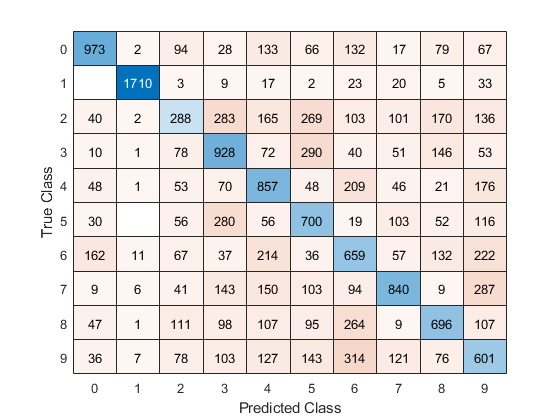

accuracy = 0.4843

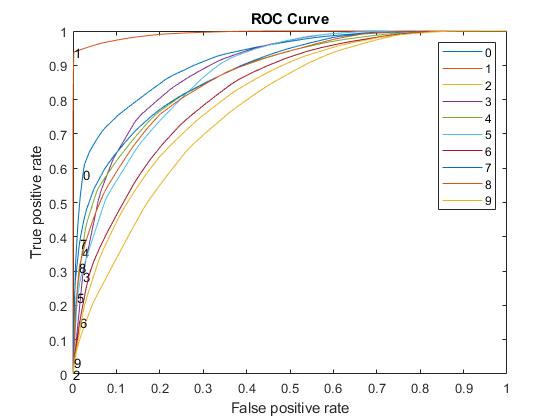

study_of_model(FinetreeModel, trainscrs, trainlabels)


classification_learner(trainscrs, trainlabels,5);

accuracy = 0.4759

    "FinetreeModel"



accuracy = 0.4186

    "MediumtreeModel"



accuracy = 0.3097

    "CoarsetreeModel"



# Multiclass classifications

function [] = classification_learner(features, labels,k_fold)
    FinetreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",100, 'Surrogate', 'off');
    [accuracy] = accuracy_result(FinetreeModel, features, labels,k_fold)
    display("FinetreeModel")
    MediumtreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",20, 'Surrogate', 'off');
    [accuracy] = accuracy_result(MediumtreeModel, features, labels,k_fold)
    display("MediumtreeModel")
    CoarsetreeModel = fitctree(features,labels,"SplitCriterion","gdi","MaxNumSplits",4, 'Surrogate', 'off');
    [accuracy] = accuracy_result(CoarsetreeModel, features, labels,k_fold)
    display("CoarsetreeModel")
    LinearDiscriminant =  fitcdiscr(features,labels,"DiscrimType","linear" , 'Gamma', 0, 'FillCoeffs', 'off');
    [accuracy] = accuracy_result(LinearDiscriminant, features, labels,k_fold)
    display("LinearDiscriminant")
    QuadraticDiscriminant = fitcdiscr(features,labels,"DiscrimType","quadratic", 'FillCoeffs', 'off');
    [accuracy] = accuracy_result(QuadraticDiscriminant, features, labels,k_fold)
    display("QuadraticDiscriminant")
    KernelNaiveBayes = fitcnb(features,labels,"DistributionNames",repmat({'Kernel'}, 1, size(features,2)), 'Kernel', 'Normal', 'Support', 'Unbounded');
    [accuracy] = accuracy_result(KernelNaiveBayes, features, labels,k_fold)
    display("KernelNaiveBayes")
    GaussianNaiveBayes = fitcnb(features,labels,"DistributionNames",repmat({'Normal'}, 1, size(features,2)));
    [accuracy] = accuracy_result(GaussianNaiveBayes, features, labels,k_fold)
    display("GaussianNaiveBayes")
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",1,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    LinearSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(LinearSVM, features, labels,k_fold)
    display("LinearSVM")
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",2,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    QuadraticSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(QuadraticSVM, features, labels,k_fold)
    display("QuadraticSVM")
    t = templateSVM("KernelFunction","polynomial","PolynomialOrder",3,"KernelScale","auto","BoxConstraint",1,"Standardize",true);
    CubicSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(CubicSVM, features, labels)
    display("CubicSVM")
    t = templateSVM("KernelFunction","gaussian", "KernelScale",1.8,"BoxConstraint",1,"Standardize",true);
    FineGuassianSVM = fitcecoc(features,labels,"Learners",t, 'Coding', 'onevsone');
    [accuracy] = accuracy_result(FineGuassianSVM, features, labels,k_fold)
    display("FineGuassianSVM")
    t = templateSVM("KernelFunction","gaussian", "KernelScale",7,"BoxConstraint",1,"Standardize",true);
    MediumGuassianSVM = fitcecoc(features,labels,"Learners",t,'Coding', 'onevsone');
    [accuracy] = accuracy_result(MediumGuassianSVM, features, labels,k_fold)
    display("MediumGuassianSVM")
    t = templateSVM("KernelFunction","gaussian", "KernelScale",28,"BoxConstraint",1,"Standardize",true);
    CoarseGaussianSVM = fitcecoc(features,labels,"Learners",t,'Coding', 'onevsone');
    [accuracy] = accuracy_result(CoarseGaussianSVM, features, labels,k_fold)
    display("CoarseGaussianSVM")
    MediumKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","euclidean","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(MediumKNN, features, labels,k_fold)
    display("MediumKNN")
    CosineKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","cosine","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(CosineKNN, features, labels,k_fold)
    display("CosineKNN")
    CubicKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","minkowski","DistanceWeight","equal","Standardize",true);
    [accuracy] = accuracy_result(CubicKNN, features, labels,k_fold)
    display("CubicKNN")
    WeightedKNN = fitcknn(features, labels,"NumNeighbors",10,"Distance","euclidean","DistanceWeight","inverse","Standardize",true);
    [accuracy] = accuracy_result(WeightedKNN, features, labels,k_fold)
    display("WeightedKNN")
    t = templateTree("MaxNumSplits" ,20);
    BoostedTrees = fitcensemble(features, labels, "Method","AdaBoostM2","Learners",t, "NumLearningCycles",30,"LearnRate",0.1);
    [accuracy] = accuracy_result(BoostedTrees, features, labels,k_fold)
    display("BoostedTrees")
    t = templateTree("MaxNumSplits" ,15999);
    BaggedTrees = fitcensemble(features, labels, "Method","Bag","Learners",t, "NumLearningCycles",30);
    [accuracy] = accuracy_result(BaggedTrees, features, labels,k_fold)
    display("BaggedTrees")
    SubspaceDiscriminant= fitcensemble(features, labels, "Method","Subspace", "Learners","discriminant", "NumLearningCycles",30, 'NPredToSample', max(1, min(25, size(labels,1) - 1)));
    [accuracy] = accuracy_result(SubspaceDiscriminant, features, labels,k_fold)
    display("SubspaceDiscriminant")
    SubspaceKNN = fitcensemble(features, labels, "Method","Subspace", "Learners","knn", "NumLearningCycles",30, 'NPredToSample', max(1, min(25, size(labels,1) - 1)));
    [accuracy] = accuracy_result(SubspaceKNN, features, labels,k_fold)
    display("SubspaceKNN")
    t = templateTree("MaxNumSplits" ,20);
    RUSBoostedTrees = fitcensemble(features, labels, "Method","RUSBoost","Learners",t, "NumLearningCycles",30,"LearnRate",0.1);
    [accuracy] = accuracy_result(RUSBoostedTrees, features, labels,k_fold)
    display("RUSBoostedTrees")
end

# Split data

function [trainimages trainlabels testimages testlabels]  = splitdata(images,labels, k)
    cv = cvpartition(size(images,3),'HoldOut',k);
    idx = cv.test;
    trainimages = images(:,:,idx);
    trainlabels = labels(idx);
    testimages = images(:,:,~idx);
    testlabels = labels(~idx);
end

# Study of model

function [] = study_of_model(model, features, labels)
    [predictlabels,score,~] = predict(model,features);
    confusionchart(labels,predictlabels);
    accuracy = nnz(labels ~= predictlabels)/length(labels)
    ClassNames = int2str(model.ClassNames);
    figure;
    for i = 1:10
        [X,Y,T,AUC,OPTROCPT] = perfcurve(labels,score(:,i),ClassNames(i));
        if (i ==2)
            hold on;
        end
        plot(X,Y);
        text(max(OPTROCPT(1)),max(OPTROCPT(2)),ClassNames(i),'FontSize',10);
    end
    xlabel('False positive rate');
    ylabel('True positive rate');
    title('ROC Curve');
    legend(ClassNames);
    hold off;
end
function [accuracy] = accuracy_result(model, features, labels, k_fold)
    partitionedModel = crossval(model, 'KFold', k_fold);
    accuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end

# Study of data

function [featuresNorm,  pcs, scrs] = study_of_data(features, labels)
    %normalize data in A, center de data and scale to have standard
    %deviation 1
    featuresNorm = normalize(features);
    %PCA pcs = principal components coefficients (Matrix changes of basis),
    %scrs = princiapl scores (featuresNorm*pcs)
    %matrix, pexp = percentage of total variance explained
    [pcs,scrs,~,~,pexp] = pca(featuresNorm);
    %Pareto 
    figure 
    H = pareto(pexp);
    title('variance srcs')
    %PCA scatter 3 first columns
    figure
    scatter3(scrs(:,1),scrs(:,2),scrs(:,3),9,labels);
    xlabel('scrs(:,1)');
    ylabel('scrs(:,2)');
    zlabel('scrs(:,3)');
    figure
    parallelcoords(scrs,"Group",labels);
end

# All points feature

function [features] = extractfeaturesallpoints(images)
    [D1, D2, nimages] = size(images);
    features = zeros(nimages, D1*D2);
    for i = 1:nimages
        im = images(:,:,i);
        features(i,:) = im(:);
    end
end


# Shape Context feature

 function [features] = extractfeatureswithShapeContext_multicenters(images, centers, radi, nbins_r, nbins_theta)
    [n_centers ~] = size(centers);
    [~, ~, nimages] = size(images);
    features = zeros(nimages, nbins_r*nbins_theta*n_centers);
    for i = 1:nimages
        im = images(:,:,i);
        feature = zeros(1,nbins_r*nbins_theta*n_centers);
        for j = 1:n_centers
           feature_aux =  ShapeContext(im, centers(j,:), radi, nbins_r, nbins_theta);
           feature(((j-1)*nbins_r*nbins_theta)+1:(j*nbins_r*nbins_theta)) = feature_aux;
        end
        features(i,:) = feature;
    end
end
function [features] = extractfeatureswithShapeContext_random_centers(images, n_centers, radi, nbins_r, nbins_theta)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, nbins_r*nbins_theta*n_centers);
    random_numbers = rand(n_centers,1);
    for i = 1:nimages
        im = images(:,:,i);
        feature = zeros(1,nbins_r*nbins_theta*n_centers);
        [~, points] = gecontour(im);
        bounding_box = boundingbox(points);
        centers = bounding_box(1,:)+random_numbers*(bounding_box(2,:)-bounding_box(1,:));
        for j = 1:n_centers
           feature_aux =  ShapeContext(im, centers(j,:), radi, nbins_r, nbins_theta);
           feature(((j-1)*nbins_r*nbins_theta)+1:(j*nbins_r*nbins_theta)) = feature_aux;
        end
        features(i,:) = feature;
    end
end

function [bounding_box] = boundingbox(points)
    bounding_box = zeros(2,2);
    bounding_box(1,:) = max(points);
    bounding_box(2,:) = min(points);
end
function [feature] = ShapeContext(im, center, radi, nbins_r, nbins_theta)
    %Hago un resize de la imagen [200 200]
    [~, points] = gecontour(im);
    [D1 D2] = size(points);
    %Calculate euclidean distance
    distances = points-center;
    distances = sqrt((distances(:,1).^2)+(distances(:,2).^2));
    %calculate r_bin
    r_bin_edges = logspace(log10(1), log10(radi), nbins_r);
    r_bin = double(zeros(D1,1));
    for i=1:length(r_bin_edges)
        s = (distances<r_bin_edges(1,i));
        r_bin = r_bin + double(s);
    end
    
    %calculate angle between two points
    distance = points-center;
    angle = atan(distance(:,2)./distance(:,1));
    min_angle = min(angle);
    if (min_angle < 0)
        angle = (angle+abs(min(angle)));
    end
    angle = (angle*2*pi)./max(angle);
    
    %calculate theta_bins
    theta_bin_edge = linspace(0,2*pi,nbins_theta);
    theta_bin = double(zeros(D1,1));
    for i=1:length(theta_bin_edge)
        s = (angle<theta_bin_edge(1,i));
        theta_bin = theta_bin + double(s);
    end
    
    feature = double(zeros(1,nbins_r*nbins_theta));
    k = 1;
    for i = 1:nbins_r
       for j = 1:nbins_theta
           features_aux = (r_bin == i) & (theta_bin == j);
           feature(k)= sum(features_aux);
           k = k+1;
       end
    end
    
end
function [contour, points] = gecontour(im)
    %lo mismo que im = im -imclose(im) o cany; Hago un resize de la imagen [200
    %200]
    im = imbinarize(im);
    im = imresize(im, [200 200]);
    [D1 D2] = size(im);
    contour = logical(zeros(D1,D2));
    points = [];
    for i = 2:(D1-1)
        for j = 2:(D2-1)
            if ((~im(i,j-1) || ~im(i,j+1) || ~im(i+1,j) || ~im(i-1,j)) && im(i,j))
               contour(i,j) = true;
               points = [points; [i j]];
            end
        end
    end
end

# Fast-Fourier(Características de contorn) 

function [features] = extractfeatureswithfourier(images,Ndescriptors)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, Ndescriptors);
    for i = 1:nimages
        im = images(:,:,i);
        features(i,:) = descriptor_fourier(im, Ndescriptors,false);
    end
end
function [features] = extractfeatureswithfourier_with_holes(images,Ndescriptors)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, Ndescriptors);
    for i = 1:nimages
        im = images(:,:,i);
        [D1 D2] = size(features);
        descriptor = descriptor_fourier(im, Ndescriptors,true);
        [d1 d2] = size(descriptor);
        if D2 < d2
           features_aux = zeros(D1,d2);
           features_aux(:,1:D2) = features;
           features = features_aux;
        elseif (d2<D2)
           descriptor_aux = zeros(1,D2);
           descriptor_aux(1,1:d2) = descriptor;
           descriptor = descriptor_aux;
        end
        features(i,:) = descriptor;
    end
end

function [descriptor] = descriptor_fourier(im, Ndescriptors, forats)
    [d1 d2 d3] = size(im);
    im = imbinarize(im);
    im = imresize(im, [300 300]);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + 1i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim els descriptros
       
    descriptor = descriptor(1:Ndescriptors);
    %log del resultat es opcional, absoluto porque la classificacion en
    %matlab no puede ser imaginario
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    if (~forats)
           return
    end
    
    
    %descriptor fourier forats
    im = imcomplement(im);
    mark=true(size(im));
    mark(2:end-1,2:end-1) = 0;
    dilc = imreconstruct(mark,im);
    res = ~dilc;
    im = xor(res,im);
    im = imcomplement(im);
    [BW, numberOfObject] = bwlabel(im);
    for i = 1:numberOfObject
        descriptors_aux = descriptor_fourier(double(BW == i), Ndescriptors, false);
        descriptor = [descriptor descriptors_aux];
    end
end


# HOG Features(Histogram of oriented gradients)

[https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html](https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html)

function [features] = extractfeatureswithHOG(images, cellSize)
    im = images(:,:,1);
    im = imbinarize(im);
    im = imresize(im, [28 28]);
    hogFeatureSize = length(extractHOGFeatures(im, 'CellSize', cellSize));
    [~, ~, nimages] = size(images);
    features = zeros(nimages, hogFeatureSize);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        im = imresize(im, [28 28]);
        [feature , image] = extractHOGFeatures(im, 'CellSize', cellSize);
        
        plot(image);
        features(i,:) = feature;
    end
end

# Wavelet Scattering

[https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html](https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html)

function [features] = extractfeatureswithWaveletScattering(images)
    sf = waveletScattering2('ImageSize', [28 28]);
    [~, ~, nimages] = size(images);
    for i = 1:nimages
        im = imresize(images(:,:,i),[28 28]);
        if (i == 1)
           feature  = helperScatImages(sf,im);
           l = length(feature);
           features = zeros(nimages, l);
           features(1,:) = feature';
        else
            features(i,:)  = helperScatImages(sf,im)';
        end
    end
end
function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.
% Copyright 2018 MathWorks
    smat = featureMatrix(sf,x,'transform','log');
    features = mean(mean(smat,2),3);
end

# Number of Corners (Harris Corner Detector)

function [features] = extractfeatureswithHarrisCorner(images)
    [~, ~, nimages] = size(images);
    features = zeros(nimages, 1);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        corners =  detectHarrisFeatures(im);
        features(i,:) = length(corners);
    end    
end

# Propietats geometricas

function [features] = geometricpropieties(images)
    [~, ~, nimages] = size(images);
    features = zeros(nimages,2);
    %Area y Area de les concavitats de la figura
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        features(i,1) = sum(im(:));
        CH = bwconvhull(im);
        feature = sum(CH(:));
        features(i,2) = sum(feature)- features(i,1);
    end
    %Numero de forats
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        im = imcomplement(im);
        mark=true(size(im));
        mark(2:end-1,2:end-1) = 0;
        dilc = imreconstruct(mark,im);
        res = ~dilc;
        im = xor(res,im);
        im = imcomplement(im);
        [~, numberOfObject] = bwlabel(im);
        features(i,3) = numberOfObject;
    end
end